[s,fs] = audioread("s6.wav")

s =    -0.0042
   -0.0016
   -0.0031
   -0.0010
   -0.0031
   -0.0031
   -0.0031
   -0.0031
   -0.0026
   -0.0026


fs = 8000

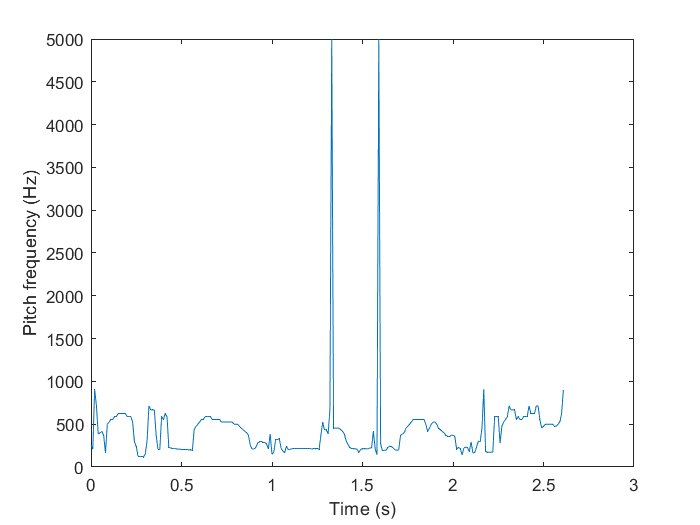

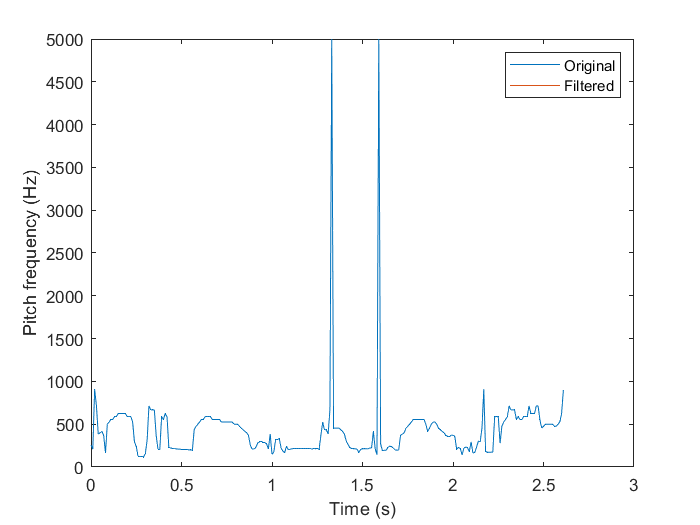

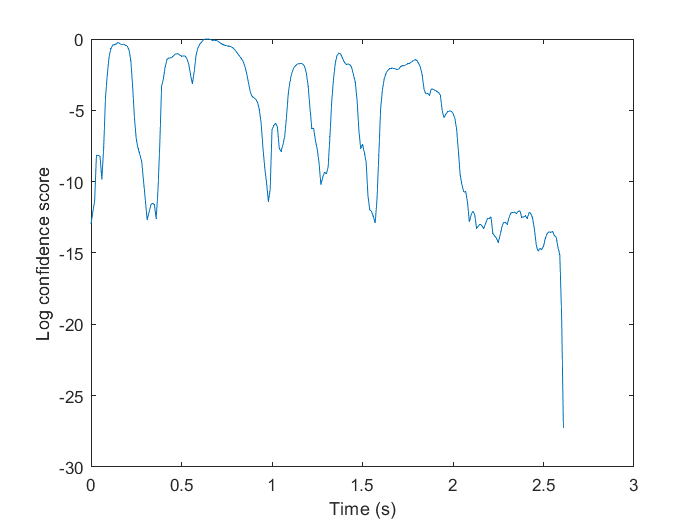

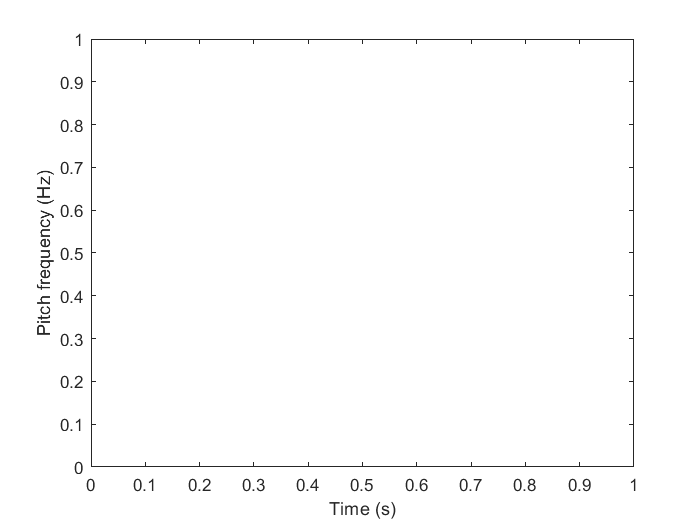

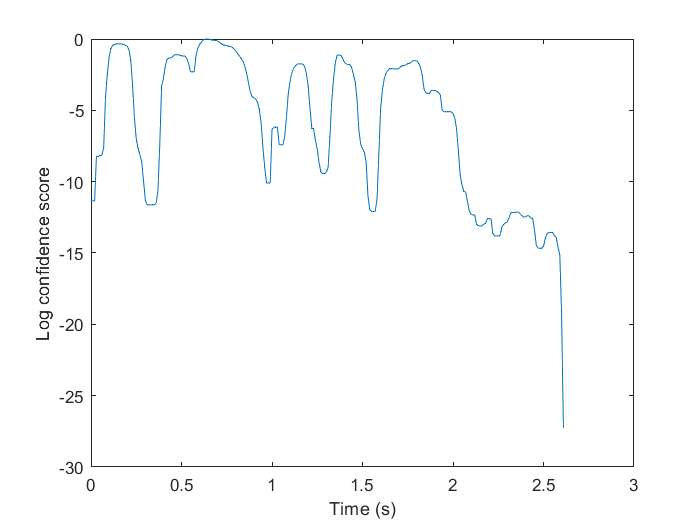

PitchDetector_Autocorrelation(s,fs,'male')

function [] = PitchDetector_Autocorrelation(s,fs,gender)
% 1. Specify whether the talker is a male or female (the program uses the talker gender to set ranges for the pitch period contour)
% Set gender to 'male' or 'female'
% 2. Read in the speech file (including determining the speech sampling rate, fs)
% 3. Convert the sampling rate to a standard value of fsout=10000 Hz for this exercise
fsout = 10000;
s = resample(s, fsout, fs);

% 4. Design and implement a bandpass filter to eliminate DC offset, 60 Hz hum, and high frequency (above 1000 Hz) signal, using the design parameters:
%    stopband from 0 to 80 Hz
%    transition band from 80 to 150 Hz
%    passband from 150 to 900 Hz
%    transition band from 900 to 970 Hz
%    stopband from 970 to 5000 Hz
%    filter length of n=301 samples
n = 301;
f = [0 80 150 900 970 5000]/(fsout/2);
a = [0 0 1 1 0 0];
b = firpm(n-1, f, a);
s_filtered = filter(b, 1, s);

% 5. Save both the full band speech and the bandpass filtered speech files for processing and comparison
audiowrite('speech_file_full.wav', s, fsout);
audiowrite('speech_file_filtered.wav', s_filtered, fsout);

% 6. Play both the original and bandpass filtered speech files to be sure that the filtering worked properly
sound(s, fsout);
pause(length(s)/fsout);
sound(s_filtered, fsout);

% 7. Block the signal into frames of length L=400 samples (corresponding to 40 msec in duration), with frame shift of R=100 samples (corresponding to 10 msec shift duration)
L = 400;
R = 100;
num_frames = floor((length(s_filtered)-L)/R) + 1;
frames = zeros(L, num_frames);
for i = 1:num_frames
    frames(:,i) = s_filtered((i-1)*R+1:(i-1)*R+L);
end

% 8. Compute the frame-by-frame modified correlation between the frames of signal specified as:
%    s1[n] = [s[n],s[n + 1],...,s[n + L-1]],
%    s2[n]=[s[n],s[n +1],...,sn +L+pdhigh -1],
%    where n is the starting sample of the current frame, and pdhigh is the longest anticipated pitch period (based on the gender of the speaker) and is specified as:
%    pdhigh=fsout/150 for females and fsout/75for males
%    (Hint: Use the MATLAB function xcorr to compute the modified correlation between s1[n] and s2[n] as it is considerably faster than any other implementation)
if strcmp(gender, 'male')
    pdhigh = fsout/75;
else
    pdhigh = fsout/150;
end
pitch_periods = zeros(1, num_frames);
for i = 1:num_frames
    s1 = frames(:,i);
    s2 = [s1(1:end-pdhigh); zeros(round(pdhigh),1)];
    r = xcorr(s1, s2);
    r = r(L:end);
    [~, locs] = findpeaks(r);
    if isempty(locs)
        pitch_periods(i) = NaN;
    else
        pitch_periods(i) = locs(1);
    end
end

% Plot pitch period contour
t = (0:num_frames-1)*R/fsout;
pitch_freqs = fsout./pitch_periods;
figure;
plot(t, pitch_freqs);
xlabel('Time (s)');
ylabel('Pitch frequency (Hz)');

%9.Compute the frame-by-frame modified correlation between the frames of signal with a longer anticipated pitch period.
pdlow = round(fsout/300);
pitch_periods_max = zeros(1, num_frames);
confidence_scores = zeros(1, num_frames);
for i = 1:num_frames
    s1 = frames(:,i);
    s2 = [s1(1:end-pdhigh); zeros(round(pdhigh),1)];
    r = xcorr(s1, s2);
    r = r(L:end);
    [~, locs] = findpeaks(r(pdlow:pdhigh));
    if isempty(locs)
        pitch_periods_max(i) = NaN;
        confidence_scores(i) = NaN;
    else
        [~, max_loc] = max(r(locs+pdlow-1));
        pitch_periods_max(i) = locs(max_loc)+pdlow-1;
        confidence_scores(i) = r(pitch_periods_max(i));
    end
end

%10.Apply a confidence threshold to the pitch periods
log_confidence_scores = log(confidence_scores);
log_confidence_scores(isnan(log_confidence_scores)) = -Inf;
log_confidence_scores = log_confidence_scores - max(log_confidence_scores);
log_confidence_threshold = 0.75 * max(log_confidence_scores);
pitch_periods_max(log_confidence_scores < log_confidence_threshold) = 0;

%11.Plot the original and filtered pitch period contours and the log confidence score.
pitch_freqs_max = fsout./pitch_periods_max;
figure;
plot(t, pitch_freqs, t, pitch_freqs_max);
xlabel('Time (s)');
ylabel('Pitch frequency (Hz)');
legend('Original', 'Filtered');
figure;
plot(t, log_confidence_scores);
xlabel('Time (s)');
ylabel('Log confidence score');

%12.Smooth the pitch period contour and the log confidence score.
pitch_freqs_max_smoothed = medfilt1(pitch_freqs_max, 5);
log_confidence_scores_smoothed = medfilt1(log_confidence_scores, 5);

%13.Plot the smoothed pitch period contour and the log confidence score.
figure;
plot(t, pitch_freqs_max_smoothed);
xlabel('Time (s)');
ylabel('Pitch frequency (Hz)');
figure;
plot(t, log_confidence_scores_smoothed);
xlabel('Time (s)');
ylabel('Log confidence score');

%14.Save the pitch periods and the log confidence score to a file.
save('out_autoc.mat', 'pitch_periods_max', 'log_confidence_scores_smoothed');
end